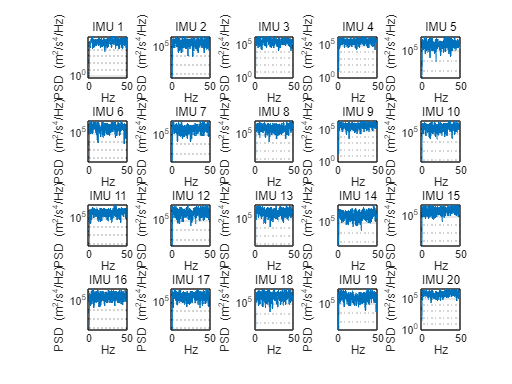

% 설정
n_files = 20;
cutoff_Hz = 0.3;
segment_start = 20;
segment_end = 38;
psd_rms = zeros(n_files, 1);

figure;
for k = 1:n_files
    filename = sprintf('imu%d.csv', k);
    
    if isfile(filename)
        data = readtable(filename);
        t = data.Time_ms / 1000;
        Az = data.AccelZ_g * 9.80665;
        dt = mean(diff(t));
        fs = 1 / dt;

        % 고역통과 필터
        [b, a] = butter(4, cutoff_Hz / (fs/2), 'high');
        Az_filtered = filtfilt(b, a, Az);

        % 분석 구간 추출
        idx = (t >= segment_start) & (t <= segment_end);
        Az_seg = Az_filtered(idx);

        % PSD 계산
        [Pxx, f] = pwelch(Az_seg, hamming(1024), [], [], fs);

        % PSD 기반 RMS 계산
        psd_rms(k) = sqrt(trapz(f, Pxx));

        % PSD 시각화 (subplot 4x5)
        subplot(4, 5, k);
        semilogy(f, Pxx, 'LineWidth', 1.2);
        title(sprintf('IMU %d', k));
        xlabel('Hz'); ylabel('PSD (m^2/s^4/Hz)');
        grid on;
    else
        fprintf('파일 %s 없음\n', filename);
        psd_rms(k) = NaN;
    end
end


% 결과 테이블 출력
T_psd = table((1:n_files)', psd_rms, ...
    'VariableNames', {'IMU_File', 'Heave_PSD_RMS_mps2'});
disp(T_psd);

    IMU_File    Heave_PSD_RMS_mps2
    ________    __________________

        1             3125.4      
        2             4302.7      
        3             4762.6      
        4             5104.2      
        5             5296.6      
        6             5594.9      
        7             5464.5      
        8             5853.1      
        9             5676.8      
       10             5427.6      
       11             5454.8      
       12             6534.3      
       13             6233.3      
       14               6186      
       15             6044.7      
       16             4335.1      
       17             6314.4      
       18             6007.5      
       19               6567      
       20             6301.5      




% 그룹별 평균 계산 (5개씩)
group_rms = [
    mean(psd_rms(1:5), 'omitnan');
    mean(psd_rms(6:10), 'omitnan');
    mean(psd_rms(11:15), 'omitnan');
    mean(psd_rms(16:20), 'omitnan')
];
T_group = table((1:4)', group_rms, ...
    'VariableNames', {'GroupIndex', 'Heave_PSD_RMS_Group_mps2'});
disp('--- 그룹별 Heave PSD RMS 평균 ---');

--- 그룹별 Heave PSD RMS 평균 ---


disp(T_group);

    GroupIndex    Heave_PSD_RMS_Group_mps2
    __________    ________________________

        1                  4518.3         
        2                  5603.4         
        3                  6090.6         
        4                  5905.1         

